clc
clear all

TSST = readtable('SST.xlsx');

T = readtable('srca.xlsx','Sheet','endpoint');
%%Sr/Ca monthly interpolation for 1671.583 - 2007.583
T.SrCa(T.SrCa == 0) = nan;
T.RSD(T.RSD == 0) = nan;
Year = flip(fillmissing(T.Winters,"linear","SamplePoints",T.Depth)); %fill gap and flip
SrCa = flip(T.SrCa); %flip first to match age model
SrCaerror = flip(T.RSD).*SrCa/100;
[SrCa,~] = fillmissing(SrCa,"linear","SamplePoints",Year); %fill gap 
[SrCaerror,~] = fillmissing(SrCaerror,"linear","SamplePoints",Year);
yearsst = [(1671+1/12*7):1/12:(2007+1/12*7)]'; %1671.583 - 2007.583
srcamonthly = interp1(Year,SrCa,yearsst,'linear',"extrap");
srcaerrorindividual = interp1(Year,SrCaerror,yearsst,'linear',"extrap");
srcaerrlongterm = 0.006;
srcaerrormonthly = sqrt(srcaerrorindividual.^2+srcaerrlongterm^2);

find(srcamonthly == max(srcamonthly))

ans = 2125

yearsst(2125)

ans = 1.8486e+03


find(srcamonthly == min(srcamonthly))

ans = 621

yearsst(621)

ans = 1.7233e+03


max(movmean(srcamonthly,13))

ans = 9.1540

min(movmean(srcamonthly,13))

ans = 8.8415

max(movmean(srcamonthly,13))-min(movmean(srcamonthly,13))

ans = 0.3125


max(movmean(srcamonthly,121))

ans = 8.9977

min(movmean(srcamonthly,121))

ans = 8.8910

max(movmean(srcamonthly,121))-min(movmean(srcamonthly,121))

ans = 0.1067

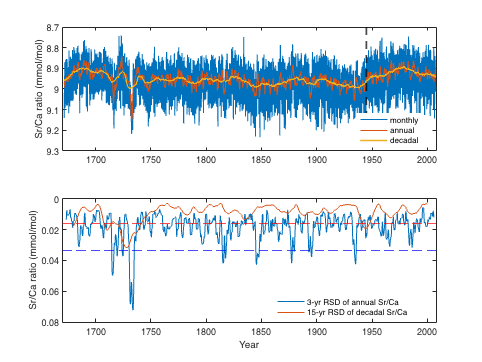

%Figure
clf('reset')
subplot(2,1,1)
hold on
plot(yearsst,srcamonthly)
mon13mean = movmean(srcamonthly,13);
mon121mean = movmean(srcamonthly,121);
plot(yearsst,mon13mean,'linewidth',1)
plot(yearsst,mon121mean,'linewidth',1.5)
ipt = findchangepts(srcamonthly,'Statistic','linear');
xline(yearsst(ipt),'--k','LineWidth',2)
set(gca, 'ydir','reverse')
set(gca,'xlim',[1670 2008])
ylabel('Sr/Ca ratio (mmol/mol)')
box on
lg1=legend ('monthly','annual','decadal');
set(lg1,'box','off','Location','best')

subplot(2,1,2)
hold on 
std3 = movstd(mon13mean,37);
std10 = movstd(mon121mean,181);


std3(1:18,:)=nan;
std3(end-18:end,:)=nan;
std10(1:90,:)=nan;
std10(end-90:end,:)=nan;

hold on
plot(yearsst,std3)
plot(yearsst,std10)

thrhld3 = 2*mean(std3(3362+18:end-19));
%+1.96*std(std3(3362:end));
thrhld10 = 2*mean(std10(3362+90:end-91));
% +1.96*std(std10(281:end-5));
yline(thrhld3,'--b')
yline(thrhld10,'--r')


ylabel('Sr/Ca ratio (mmol/mol)')
set(gca, 'ydir','reverse')
set(gca,'xlim',[1670 2008])

xlabel('Year')
box on 
lg=legend ('3-yr RSD of annual Sr/Ca','15-yr RSD of decadal Sr/Ca');
set(lg,'box','off','Location','best')

depth = T.Depth;
N = T.Winters;
[index,yr] = find(~isnan(N));
AER=diff(depth(index)); %annual extension rate
AER = flip(AER);
yr_aug = (1672:2007)'; %annual mean extenison rate and Sr/Ca 1672 = 1671 August to 1672 July
gap = (1:12:4033)';

ASrCa=zeros(size(yr_aug,1),1);

for i=1:size(yr_aug,1);
    t=srcamonthly(gap(i):(gap(i+1)-1));
    ASrCa(i) = mean(t,'omitnan');
i=i+1;
end

ARSrCa=zeros(size(yr_aug,1),1);
for i=1:size(yr_aug,1);
    t=srcamonthly(gap(i):(gap(i+1)-1));
    ARSrCa(i) = max(t) - min(t);
i=i+1;
end
%%

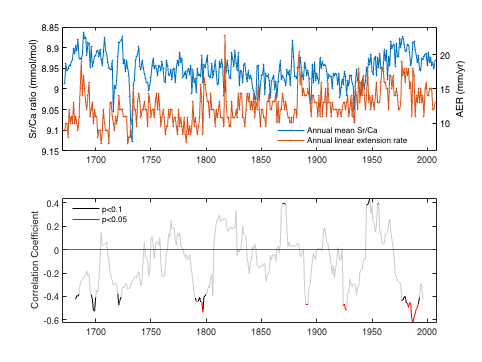

clf('reset')

subplot(2,1,1)

yyaxis left
plot(yr_aug,ASrCa,'.-')
set(gca, 'ydir','reverse')
ylabel('Sr/Ca ratio (mmol/mol)')

yyaxis right
hold on
plot(yr_aug,AER,'.-')
ylabel('AER (mm/yr)')

set(gca,'xlim',[1670 2008])

box on 
lg=legend ('Annual mean Sr/Ca','Annual linear extension rate');
set(lg,'box','off','Location','best')

ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';

subplot(2,1,2)

[r, p, n] = movcorr(detrend(AER), detrend(ASrCa), 21);
r(1:10,:) = nan;
r(end-10:end,:) = nan;
plot(yr_aug,r,'color',[0.8 0.8 0.8],'LineWidth',1)
hold on
nonsig2 = find(p>0.1);
r(nonsig2) = nan;
plot(yr_aug,r,'k','LineWidth',1)

nonsig = find(p>0.05);
r(nonsig) = nan;
plot(yr_aug,r,'r','LineWidth',1)


yline(0)
set(gca,'xlim',[1670 2008])

ylabel('Correlation Coefficient')
lg=legend ('','p<0.1','p<0.05');
set(lg,'box','off','Location','best')

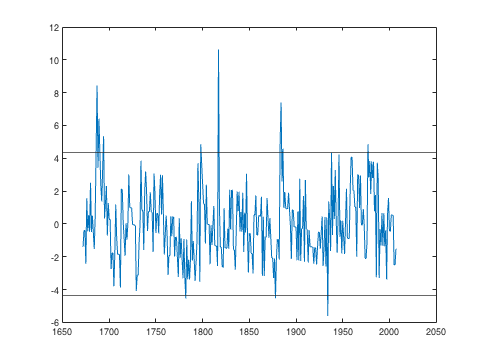

clf
AER_d = detrend(AER);
plot(yr_aug,AER_d)
yline(mean(AER_d)+2*std(AER_d))
yline(mean(AER_d)-2*std(AER_d))

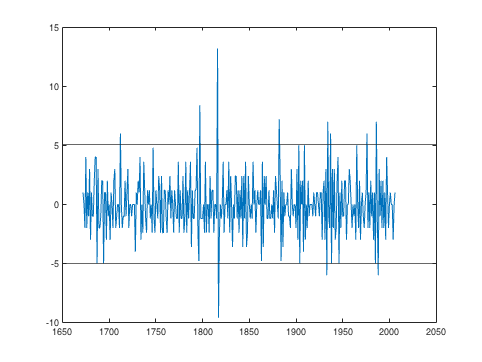

clf
AER_d = diff(detrend(AER));
plot(yr_aug(1:end-1),AER_d)
yline(mean(AER_d)+2*std(AER_d))
yline(mean(AER_d)-2*std(AER_d))

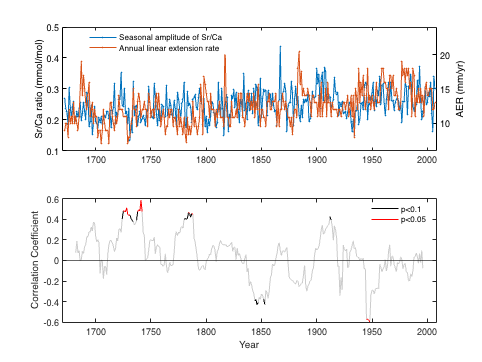

clf
subplot(2,1,1)
yyaxis left
plot(yr_aug,ARSrCa,'.-')
ylabel('Sr/Ca ratio (mmol/mol)')

yyaxis right
hold on
plot(yr_aug,AER,'.-')
ylabel('AER (mm/yr)')
set(gca,'xlim',[1670 2008])

box on 
lg=legend ('Seasonal amplitude of Sr/Ca','Annual linear extension rate');
set(lg,'box','off','Location','best')

ax = gca;
ax.YAxis(1).Color = 'k';
ax.YAxis(2).Color = 'k';

subplot(2,1,2)

[r, p, n] = movcorr(detrend(AER), detrend(ARSrCa), 21);
r(1:10,:) = nan;
r(end-10:end,:) = nan;
plot(yr_aug,r,'color',[0.8 0.8 0.8],'LineWidth',1)
hold on
nonsig2 = find(p>0.1);
r(nonsig2) = nan;
plot(yr_aug,r,'k','LineWidth',1)

nonsig = find(p>0.05);
r(nonsig) = nan;
plot(yr_aug,r,'r','LineWidth',1)


yline(0)
set(gca,'xlim',[1670 2008])

ylabel('Correlation Coefficient')
lg=legend ('','p<0.1','p<0.05');
set(lg,'box','off','Location','best')
xlabel('Year')

% % test AER and Sr/Ca relationship
[r,p] = corr(ASrCa,AER)

r = -0.1824

p = 7.8084e-04

[r,p] = corr(diff(ASrCa),diff(AER))

r = -0.1011

p = 0.0645

[r,p] = corr(detrend(ASrCa),detrend(AER))

r = -0.2180

p = 5.5862e-05

% 
k=1; %sampling frequency 1 samples a year 
% %cutoff frequency K month = 1/K samples/yr 
% 
[m1,n1]=butter(5,(1/21)/(0.5*k),'low');
ASrCa_LPF = filtfilt(m1,n1,detrend(ASrCa));
AER_LPF = filtfilt(m1,n1,detrend(AER));

[r p] = corr(diff(ASrCa_LPF),diff(AER_LPF))

r = -0.2024

p = 1.9245e-04

[r p] = corr(ASrCa_LPF,AER_LPF)

r = -0.4387

p = 3.0993e-17

n =length(ASrCa_LPF);
r1 = autocorr(ASrCa_LPF,1);
r1= r1(2);
r2=autocorr(AER_LPF,1);
r2 = r2(2);
nadj = n.*(1-r1.*r2)./(1+r1.*r2)

nadj = 4.4512

t_stat = r * sqrt((nadj - 2) / (1 - r^2));
p_adj = 2 * (1 - tcdf(abs(t_stat), nadj - 2))

p_adj = 0.5115

% % test AER and Sr/Ca relationship
[r,p] = corr(ARSrCa,AER)

r = 0.1979

p = 2.6251e-04

[r,p] = corr(diff(ARSrCa),diff(AER))

r = 0.1330

p = 0.0149

[r,p] = corr(detrend(ARSrCa),detrend(AER))

r = 0.0367

p = 0.5025

% 
k=1; %sampling frequency 1 samples a year 
% %cutoff frequency K month = 1/K samples/yr 
% 
[m1,n1]=butter(5,(1/21)/(0.5*k),'low');
ARSrCa_LPF = filtfilt(m1,n1,ARSrCa);
AER_LPF = filtfilt(m1,n1,AER);

[r p] = corr(ARSrCa_LPF,AER_LPF)

r = 0.4233

p = 4.8430e-16

n =length(ARSrCa_LPF);
r1 = autocorr(ARSrCa_LPF,1);
r1= r1(2);
r2=autocorr(AER_LPF,1);
r2 = r2(2);
nadj = n.*(1-r1.*r2)./(1+r1.*r2)

nadj = 4.5152

t_stat = r * sqrt((nadj - 2) / (1 - r^2));
p_adj = 2 * (1 - tcdf(abs(t_stat), nadj - 2))

p_adj = 0.5217

TSST.Mon = categorical(TSST.Mon);
Tsummer = vertcat(TSST((TSST.Mon=='1'),:),TSST((TSST.Mon=='2'),:),TSST((TSST.Mon=='3'),:),TSST((TSST.Mon=='12'),:));
Tsummer = sortrows(Tsummer,2);
yr_s = yr_aug;
yr_w = yr_aug(1:end-1);

summersrca = zeros(336,1);
gap = (1:4:1345)';
for i=1:336;
    t=Tsummer.SrCa(gap(i):(gap(i+1)-1));
    summersrca(i) = mean(t,'omitnan');
i=i+1;
end


summersrcamin = zeros(336,1);
gap = (1:4:1345)';
for i=1:336;
    t=Tsummer.SrCa(gap(i):(gap(i+1)-1));
    summersrcamin(i) = min(t);
i=i+1;
end


summersrcaerror = zeros(336,1);
gap = (1:4:1345)';
for i=1:336;
    t=Tsummer.SrCaError(gap(i):(gap(i+1)-1));
    summersrcaerror(i) = rms(t,'omitnan');
end

Twinter = vertcat(TSST((TSST.Mon=='6'),:),TSST((TSST.Mon=='7'),:),TSST((TSST.Mon=='8'),:),TSST((TSST.Mon=='9'),:));
Twinter = sortrows(Twinter,2);
Twinter = Twinter(3:1342,:);
gap = (1:4:1341)';

wintersrca = zeros(335,1);
for i=1:335;
    t=Twinter.SrCa(gap(i):(gap(i+1)-1));
    wintersrca(i) = mean(t,'omitnan');
i=i+1;
end

wintersrcaerr = zeros(335,1);
for i=1:335;
    t=Twinter.SrCaError(gap(i):(gap(i+1)-1));
    wintersrcaerr(i) = rms(t,'omitnan');
i=i+1;
end

wintersrcamax = zeros(335,1);
for i=335;
    t=Twinter.SrCa(gap(i):(gap(i+1)-1));
    wintersrcamax(i) = max(t);
i=i+1;
end





[r,p] = corr(summersrca,AER)

r = -0.2478

p = 4.2938e-06

[r,p] = corr(summersrcamin,AER)

r = -0.2636

p = 9.5586e-07

max(srcamonthly)

ans = 9.2338

max(ASrCa)

ans = 9.1278

max(movmean(srcamonthly,120))

ans = 8.9970


min(srcamonthly)

ans = 8.7413

min(ASrCa)

ans = 8.8633

min(movmean(srcamonthly,120))

ans = 8.8915


max(srcamonthly) - min(srcamonthly)

ans = 0.4925

max(ASrCa) - min(ASrCa)

ans = 0.2645

max(movmean(srcamonthly,120)) - min(movmean(srcamonthly,120))

ans = 0.1055

RC3= readtable('Running corr.xlsx','sheet','ERSSTSrCa1886');

yrrc3 = RC3.year_;
corr3=RC3.x__Corr___;
p3=RC3.x_Prob___;
% 2.5%
l5 = RC3.x2_5cl;
% 97.50%
l6 = RC3.x97_5cl;

RC4= readtable('Running corr.xlsx','sheet','HadISSTSrCa1886');

yrrc4 = RC4.year_;
corr4=RC4.x__Corr___;
p4=RC4.x_Prob___;
% 2.5%
l7 = RC4.x2_5cl;
% 97.50%
l8 = RC4.x97_5cl;
clf('reset')

subplot (3,1,1)
hold on
plot(yrrc3,corr3,'LineWidth',1.5,'color',[0.8 0.5 0])
plot(yrrc4,corr4,'LineWidth',1.5,'color',[0.6 0.2 0])
plot(yrrc3,l5,'--','LineWidth',1.5,'color',[0.8 0.5 0])
plot(yrrc3,l6,'--','LineWidth',1.5,'color',[0.8 0.5 0])
plot(yrrc4,l7,'--','LineWidth',1.5,'color',[0.6 0.2 0])
plot(yrrc4,l8,'--','LineWidth',1.5,'color',[0.6 0.2 0])
yline(0,'-k')
set(gca,'xlim',[1900 2007.59])
patch([1900 1960 1960 1900],[1 1 -1 -1],[30 30 30]/256,'Edgecolor','none','Facealpha',0.2)
leg = legend('ERSSTv5-Sr/Ca','HadISST1-Sr/Ca')

leg =   Legend (ERSSTv5-Sr/Ca, HadISST1-Sr/Ca) with properties:

         String: {'ERSSTv5-Sr/Ca'  'HadISST1-Sr/Ca'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.6973 0.8520 0.1937 0.0631]
          Units: 'normalized'

  Show all properties


set(leg,'Box','off','location','best')
ylabel('Correlation Coefficient')
hold off
box on

RC3= readtable('Running corr.xlsx','sheet','ERSSTSrCawinter');

yrrc3 = RC3.year_;
corr3=RC3.x__Corr___;
p3=RC3.x_Prob___;
% 2.5%
l5 = RC3.x2_5cl;
% 97.50%
l6 = RC3.x97_5cl;

RC4= readtable('Running corr.xlsx','sheet','HadISSTSrCawinter');

yrrc4 = RC4.year_;
corr4=RC4.x__Corr___;
p4=RC4.x_Prob___;
% 2.5%
l7 = RC4.x2_5cl;
% 97.50%
l8 = RC4.x97_5cl;

subplot (3,1,2)
hold on
plot(yrrc3,corr3,'LineWidth',1.5,'color',[0.8 0.5 0])
plot(yrrc4,corr4,'LineWidth',1.5,'color',[0.6 0.2 0])
plot(yrrc3,l5,'--','LineWidth',1.5,'color',[0.8 0.5 0])
plot(yrrc3,l6,'--','LineWidth',1.5,'color',[0.8 0.5 0])
plot(yrrc4,l7,'--','LineWidth',1.5,'color',[0.6 0.2 0])
plot(yrrc4,l8,'--','LineWidth',1.5,'color',[0.6 0.2 0])
yline(0,'-k')
set(gca,'xlim',[1900 2007.59])
patch([1900 1960 1960 1900],[1 1 -1 -1],[30 30 30]/256,'Edgecolor','none','Facealpha',0.2)
leg = legend('ERSSTv5-Sr/Ca','HadISST1-Sr/Ca')

leg =   Legend (ERSSTv5-Sr/Ca, HadISST1-Sr/Ca) with properties:

         String: {'ERSSTv5-Sr/Ca'  'HadISST1-Sr/Ca'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.6973 0.5520 0.1937 0.0631]
          Units: 'normalized'

  Show all properties


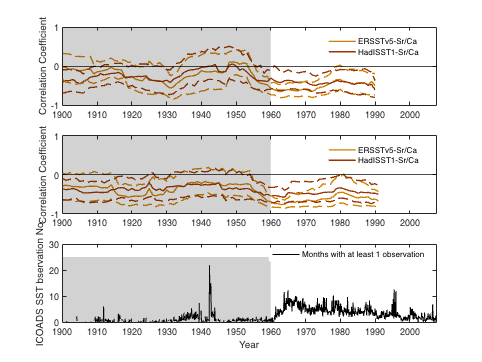

set(leg,'Box','off','location','best')
ylabel('Correlation Coefficient')
hold off
box on

subplot(3,1,3)
time=[1800:1/12:2024-1/12]';
observatonNo=ncread('icoads_sst_n_48-56E_-16--8N_n.nc','sst');
index2 = observatonNo==0;
observatonNo(index2)=nan;
hold on 
plot(time,observatonNo,'-k','LineWidth',0.5)
patch([1900 1960 1960 1900],[25 25 0 0],[30 30 30]/256,'Edgecolor','none','Facealpha',0.2)
set(gca,'xlim',[1900 2007.59])
ylabel('ICOADS SST bservation No.')
legend({'Months with at least 1 observation'})
set(legend,'Box','off')
box on
xlabel('Year')

TSSTA = readtable('SSTA.xlsx');

Date = TSSTA.Date;
ERSSTA=TSSTA.ERSSTv5;
HadISSTA=TSSTA.HadISST1;
HadSSTA=TSSTA.HadSST4;
SrCaA=TSSTA.SrCa;
SSTA1 = SrCaA/-0.061;
SSTA2 = SrCaA/-0.084;
SD_a1 = (1/-0.061).*srcaerrormonthly;
SD_a2 = - ((SrCaA./((-0.061)^2))*0.02);
SD_a3 = -0.06;
SSTA_Err = sqrt(SD_a1.^2+SD_a2.^2+SD_a3.^2);

gap = (4:12:4024)';
yr = (1672:2006)';

ASSTA1 = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=SSTA1(gap(i):(gap(i+1)-1));
    ASSTA1(i) = mean(t);
i=i+1;
end

ASSTA2 = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=SSTA2(gap(i):(gap(i+1)-1));
    ASSTA2(i) = mean(t);
i=i+1;
end

ASSTA_Err = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=SSTA_Err(gap(i):(gap(i+1)-1));
    ASSTA_Err(i) = rms(t);
i=i+1;
end

AERSSTA_Err = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=TSST.ERSSTv3error(gap(i):(gap(i+1)-1));
    AERSSTA_Err(i) = rms(t);
i=i+1;
end


AERSSTA = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=ERSSTA(gap(i):(gap(i+1)-1));
    AERSSTA(i) = mean(t);
i=i+1;
end

AHadISSTA = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=HadISSTA(gap(i):(gap(i+1)-1));
    AHadISSTA(i) = mean(t);
i=i+1;
end

AHadSSTA = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=HadSSTA(gap(i):(gap(i+1)-1));
    AHadSSTA(i) = mean(t);
i=i+1;
end

AICOADSSSTA = zeros(size(yr,1),1);
for i=1:size(yr,1);
    t=TSSTA.ICOADS(gap(i):(gap(i+1)-1));
    AICOADSSSTA(i) = mean(t);
i=i+1;
end

clf('reset')
subplot(4,1,2)
hold on 
plot(Date,SSTA1,LineWidth=1)
plot(Date,SSTA2,LineWidth=1)
plot(Date,TSSTA.ICOADS,'color',[0.4940 0.1840 0.5560],'LineWidth',1)
SSTA_err1 = vertcat(SSTA1+SSTA_Err,flipud(SSTA1-SSTA_Err));
SSTA_err2 = vertcat(SSTA2+SSTA_Err,flipud(SSTA2-SSTA_Err));
patch_date = vertcat(Date,flipud(Date));
patch(patch_date,SSTA_err1,[0 94 240]/256,'Edgecolor','none','Facealpha',0.4)
patch(patch_date,SSTA_err2,[240 94 0]/256,'Edgecolor','none','Facealpha',0.4)

set(gca,'XLim',[1850 2050])
lg = legend('Coral SSTA -0.061','Coral SSTA -0.084','ICOADS')

lg =   Legend (Coral SSTA -0.061, Coral SSTA -0.084, ICOADS) with properties:

         String: {'Coral SSTA -0.061'  'Coral SSTA -0.084'  'ICOADS'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.6830 0.6060 0.2080 0.0905]
          Units: 'normalized'

  Show all properties


box on
set(lg,'box','off','location','best')
ylabel('SSTA (°C)')


subplot(4,1,1)
hold on 
plot(Date,SSTA1,LineWidth=1)
plot(Date,SSTA2,LineWidth=1)
plot(Date,HadSSTA,LineWidth=1)
SSTA_err1 = vertcat(SSTA1+SSTA_Err,flipud(SSTA1-SSTA_Err));
SSTA_err2 = vertcat(SSTA2+SSTA_Err,flipud(SSTA2-SSTA_Err));
patch_date = vertcat(Date,flipud(Date));
patch(patch_date,SSTA_err1,[0 94 240]/256,'Edgecolor','none','Facealpha',0.4)
patch(patch_date,SSTA_err2,[240 94 0]/256,'Edgecolor','none','Facealpha',0.4)

set(gca,'XLim',[1850 2050])
lg = legend('Coral SSTA -0.061','Coral SSTA -0.084','HadSST4')

lg =   Legend (Coral SSTA -0.061, Coral SSTA -0.084, HadSST4) with properties:

         String: {'Coral SSTA -0.061'  'Coral SSTA -0.084'  'HadSST4'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.6830 0.8250 0.2080 0.0905]
          Units: 'normalized'

  Show all properties


box on
set(lg,'box','off','location','best')
ylabel('SSTA (°C)')


subplot(4,1,3)
hold on 
plot(Date,SSTA1,LineWidth=1)
plot(Date,SSTA2,LineWidth=1)
plot(Date,TSSTA.HadISST1,'color',[0.4660 0.6740 0.1880],'LineWidth',1)
SSTA_err1 = vertcat(SSTA1+SSTA_Err,flipud(SSTA1-SSTA_Err));
SSTA_err2 = vertcat(SSTA2+SSTA_Err,flipud(SSTA2-SSTA_Err));
patchdate = vertcat(Date,flipud(Date));
patch(patch_date,SSTA_err1,[0 94 240]/256,'Edgecolor','none','Facealpha',0.4)
patch(patch_date,SSTA_err2,[240 94 0]/256,'Edgecolor','none','Facealpha',0.4)

set(gca,'XLim',[1850 2050])
lg = legend('Coral SSTA -0.061','Coral SSTA -0.084','HadISST1')

lg =   Legend (Coral SSTA -0.061, Coral SSTA -0.084, HadISST1) with properties:

         String: {'Coral SSTA -0.061'  'Coral SSTA -0.084'  'HadISST1'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.6830 0.3869 0.2080 0.0905]
          Units: 'normalized'

  Show all properties


box on
set(lg,'box','off','location','best')
ylabel('SSTA (°C)')

subplot(4,1,4)
hold on 
plot(Date,SSTA1,LineWidth=1)
plot(Date,SSTA2,LineWidth=1)
plot(Date,TSSTA.ERSSTv5,'color',[0.3010 0.7450 0.9330],'LineWidth',1)
SSTA_err1 = vertcat(SSTA1+SSTA_Err,flipud(SSTA1-SSTA_Err));
SSTA_err2 = vertcat(SSTA2+SSTA_Err,flipud(SSTA2-SSTA_Err));
patchdate = vertcat(Date,flipud(Date));
patch(patch_date,SSTA_err1,[0 94 240]/256,'Edgecolor','none','Facealpha',0.4)
patch(patch_date,SSTA_err2,[240 94 0]/256,'Edgecolor','none','Facealpha',0.4)

set(gca,'XLim',[1850 2050])
lg = legend('Coral SSTA -0.061','Coral SSTA -0.084','ERSSTv5')

lg =   Legend (Coral SSTA -0.061, Coral SSTA -0.084, ERSSTv5) with properties:

         String: {'Coral SSTA -0.061'  'Coral SSTA -0.084'  'ERSSTv5'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.6830 0.1679 0.2080 0.0905]
          Units: 'normalized'

  Show all properties


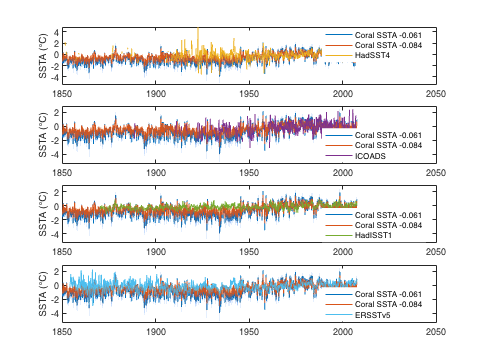

box on
set(lg,'box','off','location','best')
ylabel('SSTA (°C)')

fitlm(Date(2862:end),TSSTA.ICOADS(2862:end))

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE         tStat       pValue  
                   _________    _________    _______    __________

    (Intercept)      -19.153       2.2636    -8.4613    1.3861e-16
    x1             0.0096171    0.0011513     8.3532    3.2165e-16


Number of observations: 750, Error degrees of freedom: 748
Root Mean Squared Error: 0.808
R-squared: 0.0853,  Adjusted R-Squared: 0.0841
F-statistic vs. constant model: 69.8, p-value = 3.22e-16

0.0096171*(Date(end)-Date(2862))

ans = 0.9385

2*0.0011513*(Date(end)-Date(2862))

ans = 0.2247


fitlm(Date(2862:end),SSTA1(2862:end))

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE         tStat       pValue  
                   ________    __________    _______    __________

    (Intercept)     -28.461        1.5679    -18.152    4.5205e-65
    x1             0.014237    0.00080037     17.788    7.7449e-63


Number of observations: 1172, Error degrees of freedom: 1170
Root Mean Squared Error: 0.773
R-squared: 0.213,  Adjusted R-Squared: 0.212
F-statistic vs. constant model: 316, p-value = 7.74e-63

0.014237*(Date(end)-Date(2862))

ans = 1.3893

2*0.00080037*(Date(end)-Date(2862))

ans = 0.1562



fitlm(Date(2862:end),SSTA2(2862:end))

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE         tStat       pValue  
                   ________    __________    _______    __________

    (Intercept)     -20.668        1.1386    -18.152    4.5205e-65
    x1             0.010339    0.00058122     17.788    7.7449e-63


Number of observations: 1172, Error degrees of freedom: 1170
Root Mean Squared Error: 0.561
R-squared: 0.213,  Adjusted R-Squared: 0.212
F-statistic vs. constant model: 316, p-value = 7.74e-63

0.010339*(Date(end)-Date(2862))

ans = 1.0089

2*0.00058122*(Date(end)-Date(2862))

ans = 0.1134


fitlm(Date(2862:end),TSSTA.HadISST1(2862:end))

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate         SE         tStat       pValue  
                   _________    __________    _______    __________

    (Intercept)      -7.6904        0.6597    -11.658    8.6641e-30
    x1             0.0038767    0.00033675     11.512    3.9784e-29


Number of observations: 1172, Error degrees of freedom: 1170
Root Mean Squared Error: 0.325
R-squared: 0.102,  Adjusted R-Squared: 0.101
F-statistic vs. constant model: 133, p-value = 3.98e-29

0.0038767*(Date(end)-Date(2862))

ans = 0.3783

2*0.00033675*(Date(end)-Date(2862))

ans = 0.0657


fitlm(Date(2862:end),TSSTA.ERSSTv5(2862:end))

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate         SE         tStat       pValue  
                   _________    __________    _______    __________

    (Intercept)      -14.802       0.87771    -16.864     2.755e-57
    x1             0.0074783    0.00044804     16.691    2.8768e-56


Number of observations: 1172, Error degrees of freedom: 1170
Root Mean Squared Error: 0.432
R-squared: 0.192,  Adjusted R-Squared: 0.192
F-statistic vs. constant model: 279, p-value = 2.88e-56

0.0074783*(Date(end)-Date(2862))

ans = 0.7298

2*0.00044804*(Date(end)-Date(2862))

ans = 0.0874


fitlm(Date(2862:end),TSSTA.HadSST4(2862:end))

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate         SE         tStat       pValue  
                   _________    __________    _______    __________

    (Intercept)      -12.848        1.5568    -8.2531    4.7298e-16
    x1             0.0064856    0.00079315     8.1771    8.5696e-16


Number of observations: 1023, Error degrees of freedom: 1021
Root Mean Squared Error: 0.702
R-squared: 0.0615,  Adjusted R-Squared: 0.0605
F-statistic vs. constant model: 66.9, p-value = 8.57e-16

0.0064856*(Date(end)-Date(2862))

ans = 0.6329

2*0.00079315*(Date(end)-Date(2862))

ans = 0.1548

clf
hold on
plot(Date,movstd(SSTA1,37),LineWidth=1)
plot(Date,movstd(SSTA2,37),LineWidth=1)
plot(Date,movstd(HadSSTA,37,'omitnan'))
plot(Date,movstd(TSSTA.ICOADS,37,'omitnan'))
plot(Date,movstd(HadISSTA,37,'omitnan'))
plot(Date,movstd(ERSSTA,37,'omitnan'))
set(gca,'XLim',[1850 2050])
lg = legend('Coral SSTA -0.061','Coral SSTA -0.084','HadSST4','ICOADS',"HadISST1",'ERSSTv5')

lg =   Legend (Coral SSTA -0.061, Coral SSTA -0.084, HadSST4, ICOADS, HadISST1, ERSSTv5) with properties:

         String: {'Coral SSTA -0.061'  'Coral SSTA -0.084'  'HadSST4'  'ICOADS'  'HadISST1'  'ERSSTv5'}
       Location: 'northeast'
    Orientation: 'vertical'
       FontSize: 9
       Position: [0.6830 0.7333 0.2080 0.1726]
          Units: 'normalized'

  Show all properties


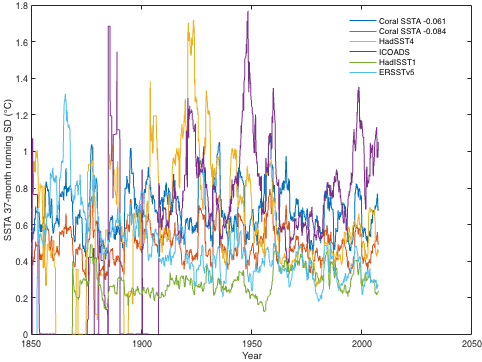

box on
set(lg,'box','off','location','best')
ylabel('SSTA 37-month running SD (°C)')
xlabel('Year')
set(gca, 'LooseInset', get(gca,'TightInset'))

TSSTA.WLS = SSTA2;
TSSTA.WLSerror = SSTA_Err;
TSSTA.ERSSTerror = TSST.ERSSTv3error;
TSSTA.Mon = categorical(TSSTA.Mon);
Tsummer = vertcat(TSSTA((TSSTA.Mon=='1'),:),TSSTA((TSSTA.Mon=='2'),:),TSSTA((TSSTA.Mon=='3'),:),TSSTA((TSSTA.Mon=='12'),:));
Tsummer = sortrows(Tsummer,2);

gap = (1:4:1345)';

summerOISST = zeros(336,1);
for i=1:336;
    t=Tsummer.OISSTv2(gap(i):(gap(i+1)-1));
    summerOISST(i) = mean(t,'omitnan');
i=i+1;
end

summerOISSTerror = zeros(336,1);
for i=1:336;
    t=Tsummer.OISSTv2error(gap(i):(gap(i+1)-1));
    summerOISSTerror(i) = rms(t,'omitnan');
i=i+1;
end

summerHadISST1 = zeros(336,1);
for i=1:336;
    t=Tsummer.HadISST1(gap(i):(gap(i+1)-1));
    summerHadISST1(i) = mean(t,'omitnan');
i=i+1;
end

summerERSST= zeros(336,1);
for i=1:336;
    t=Tsummer.ERSSTv5(gap(i):(gap(i+1)-1));
    summerERSST(i) = mean(t);
i=i+1;
end

summerERSSTerror = zeros(336,1);
for i=1:size(yr,1);
    t=Tsummer.ERSSTerror(gap(i):(gap(i+1)-1));
    summerERSSTerror(i) = rms(t,'omitnan');
end


summerICOADS= zeros(336,1);
for i=1:336;
    t=Tsummer.ICOADS(gap(i):(gap(i+1)-1));
    summerICOADS(i) = max(t);
i=i+1;
end

summerWLS = zeros(336,1);
for i=1:336;
    t=Tsummer.WLS(gap(i):(gap(i+1)-1));
    summerWLS(i) = mean(t,'omitnan');
i=i+1;
end

summerWLSerror = zeros(336,1);
for i=1:size(yr,1);
    t=Tsummer.WLSerror(gap(i):(gap(i+1)-1));
    summerWLSerror(i) = rms(t,'omitnan');
end



Twinter = vertcat(TSSTA((TSSTA.Mon=='6'),:),TSSTA((TSSTA.Mon=='7'),:),TSSTA((TSSTA.Mon=='8'),:),TSSTA((TSSTA.Mon=='9'),:));
Twinter = sortrows(Twinter,2);
Twinter = Twinter(3:1342,:);
gap = (1:4:1341)';

winterOISST = zeros(335,1);
for i=1:335;
    t=Twinter.OISSTv2(gap(i):(gap(i+1)-1));
    winterOISST(i) = mean(t,'omitnan');
i=i+1;
end

winterOISSTerror = zeros(335,1);
for i=1:335;
    t=Twinter.OISSTv2error(gap(i):(gap(i+1)-1));
    winterOISSTerror(i) = rms(t,'omitnan');
i=i+1;
end

winterHadISST1 = zeros(335,1);
for i=1:335;
    t=Twinter.HadISST1(gap(i):(gap(i+1)-1));
    winterHadISST1(i) = mean(t,'omitnan');
i=i+1;
end

winterERSST = zeros(335,1);
for i=1:335;
    t=Twinter.ERSSTv5(gap(i):(gap(i+1)-1));
    winterERSST(i) = mean(t);
i=i+1;
end

winterERSSTerror = zeros(335,1);
for i=1:size(yr,1);
    t=Twinter.ERSSTerror(gap(i):(gap(i+1)-1));
    winterERSSTerror(i) = rms(t,'omitnan');
end

winterICOADS = zeros(335,1);
for i=1:335;
    t=Twinter.ICOADS(gap(i):(gap(i+1)-1));
    winterICOADS(i) = mean(t);
i=i+1;
end

winterWLS = zeros(335,1);
for i=1:335;
    t=Twinter.WLS(gap(i):(gap(i+1)-1));
    winterWLS(i) = mean(t,'omitnan');
i=i+1;
end

winterWLSerror = zeros(335,1);
for i=1:335;
    t=Twinter.WLSerror(gap(i):(gap(i+1)-1));
    winterWLSerror(i) = rms(t,'omitnan');
i=i+1;
end



%1850-1945
fitlm(yr_w(179:274),winterWLS(179:274))

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate        SE         tStat      pValue 
                   _________    _________    ________    _______

    (Intercept)      -1.2299       2.6898    -0.45724    0.64856
    x1             0.0002697    0.0014174     0.19028     0.8495


Number of observations: 96, Error degrees of freedom: 94
Root Mean Squared Error: 0.385
R-squared: 0.000385,  Adjusted R-Squared: -0.0102
F-statistic vs. constant model: 0.0362, p-value = 0.85

fitlm(yr_s(179:274),summerWLS(179:274))

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate        SE         tStat      pValue  
                   __________    _________    _______    _________

    (Intercept)         7.825       2.9949     2.6127     0.010458
    x1             -0.0045189    0.0015782    -2.8634    0.0051688


Number of observations: 96, Error degrees of freedom: 94
Root Mean Squared Error: 0.428
R-squared: 0.0802,  Adjusted R-Squared: 0.0704
F-statistic vs. constant model: 8.2, p-value = 0.00517

fitlm(yr(179:274),ASSTA2(179:274))

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                    Estimate        SE         tStat      pValue 
                   __________    _________    _______    ________

    (Intercept)        3.0318       2.1823     1.3893     0.16803
    x1             -0.0019887    0.0011499    -1.7294    0.087017


Number of observations: 96, Error degrees of freedom: 94
Root Mean Squared Error: 0.312
R-squared: 0.0308,  Adjusted R-Squared: 0.0205
F-statistic vs. constant model: 2.99, p-value = 0.087

ASSTA2(145)=nan;
ASSTA2(146)=nan;
[ASSTA2,~] = fillmissing(ASSTA2,"linear","SamplePoints",yr); %fill gap 
summerWLS(145)=nan;
summerWLS(146)=nan;
[summerWLS,~] = fillmissing(summerWLS,"linear","SamplePoints",yr_s); %fill gap 
% remove the year from 1671-1739
summerWLS(1:68)=nan;
winterWLS(1:68)=nan;
ASSTA_Err(1:68)=nan;
ASSTA2(1:68)=nan;


% MOVCORR Moving Pearson product-moment correlation coefficient r. This is
% basically a wrapper to MOVSUM and the low-memory overhead computation of r.
% See second formula in 
%   https://en.wikipedia.org/wiki/Pearson_correlation_coefficient#For_a_sample
%
% @Synopsis
%   r = MOVCORR(x, y, k) computes r for x and y over a centered window specified
%   by k.
%
%   MOVCORR(x, y, k, missing) specifies how to treats NaNs.
%
%   MOVSUM(...,'Endpoints',endpoints) controls how the start/end of the vectors
%   are handled.
%
%   [r, p] = MOVSUM(...) also returns the p-values for each computed r.
%
%   [r, p] = MOVSUM(...,'Tail',tail) controls what kind of hypothesis test is
%   used to compute the p-values.
%
% @Input
%   x, y (required)
%     m x 1 column vectors with the data to correlate.
%
%   k (required)
%      Positive integer scalar with the window size or 1x2 array of non-negative
%      integer scalars [nB, nF] with backward & forward samples for the window.
%      If k is a scalar and is even, the window is centered on the current &
%      previous sample, e.g. ranges from i-k/2 to i+k/2-1. If k is a vector the
%      window ranges from i-nB to i+nF.
%
%   missing (optional)
%     Flag of what to do with missing values. Either 'includenan' or 'omitnan'.
%     For 'omitnan' the r values are computed pairwise, resembling the behavior
%     of CORR(...,'Rows','pairwise') - but of course much faster.
%     DEFAULT: 'includenan'
%
%   'Endpoints',endpoints (Name/value)
%     Specifies how to handle the start/end of the vectors. Either a numeric or
%     logical scalar or 'shrink', 'fill' or 'discard'. Be aware that using
%     arbitrary numeric values does not really make sense in this setting (as
%     the correlation coefficient is bound between -1 and 1). Moreover, when
%     using numeric/logical endpoints, the according p-values are set to NaN.
%     This result in unexpected NaNs: If missing=='omitnan' and endpoints is
%     numeric, then p will contain NaNs at the endpoints, despite r beeing
%     finite.
%     DEFAULT: 'shrink'
%
%   'Tail',tail (Name/value)
%     Specifies the hypothesis with which the p-values are computed. Either
%     'both', 'left' or 'right'. See CORR for more details.
%     DEFAULT: 'both'
%
%   'MinN',nMin (Name/value)
%     Positive integer scalar with the minimum number of non-NaN values in a
%     local window required for computation of r. If a window does not have the
%     required number of values, r is not computed (e.g. set to NaN). 'MinN' has
%     to be equal or smaller than the window length specified by k. This
%     option is ignored if missing=='includenan'. Setting 'MinN' > 1 when using 
%     'Endpoints'=='shrink' may cause the values at the borders to be NaN,
%     despite the 'shrink' option.
%     DEFAULT: 1 (always compute r)
%
% @Output
%   r
%     m x 1 column vector with the local Pearson correlation coefficients for
%     each mutual sample in x and y.
%
%   p
%     m x 1 column vector with the p-values for the local Pearson correlation
%     coefficients.
%
%   n
%     The number of non-NaN values in each local window. If
%     missing=='includenan', this is a scalar equal to the window size. If
%     missing=='omitnan', this is an m x 1 column vector with the number of
%     non-NaN elements in each local window. This can be used to compute the
%     degrees-of-freedom for partial correlations.
%
% @Remarks
%   - For more detailed info on the inputs & syntax see MOVSUM.
%
% @Dependencies
%   none
%
% See also CORR, MOVSUM
%
% ML-FEX ID:65342
%
% @Changelog
%   2017-12-07 (DJM): 
%     - [RELEASE] Golden.
%     - [MOD] Computation of r with NaNs + 'omitnan' now gives same results as
%       CORR(...,'Rows','pairwise').
%   2017-12-11 (DJM): 
%     - [ADD] Name-value input 'Tail' and according p-value output.
%     - [MOD] Now uses INPUTPARSER. Changes error messages for invalid inputs.
%     - [FIX] Erroneous window size computation when using k = [nB, nF].
%     - [FIX] Complex output when using numeric endpoints.
%   2017-12-12 (DJM): 
%     - [ADD] Output n.
%   2017-12-14 (DJM): 
%     - [ADD] Name-value input 'MinN'.
%     - [MOD] Now returns NaN for zero-variances, to be consistent with CORR.
%

function [r, p, n] = movcorr(x, y, k, varargin)
%% Parse inputs
[x, y, k, missing, endpoints, tail, nMin, n] ...
    = parseInputs(x, y, k, varargin);
isNumericEndpoints = ~ischar(endpoints);
if isNumericEndpoints
	% With numeric/logical endpoints, we set the method to 'fill' and set the
	% values in the end, to avoid problems when using MOVSUM on x & x^2.
	endpointVals = endpoints;
	endpoints    = 'fill';
end
%% Assemble lambda function for MOVSUM
movingSum = @(v) movsum(v, k, missing, 'Endpoints',endpoints);
%% Compute sums
sumX = movingSum(x);
sumY = movingSum(y);
%% Compute r
% Use SQRT in denominator on x & y separately to avoid under/overflow.
r = (n .* movingSum(x.*y) - sumX.*sumY) ...
 ./ (sqrt(n .* movingSum(x.^2) - sumX.^2) .* sqrt(n .* movingSum(y.^2) - sumY.^2));
%% Handle values > +/-1
% Use same method as CORR to be consistent. This will cause INFs to be NaN...
% which might be argued upon.
isExceeding = abs(r) > 1;
r(isExceeding) = r(isExceeding) ./ abs(r(isExceeding));
%% Remove invalid windows
if strcmp(missing, 'omitnan')
	r(n < nMin) = NaN; % n is vector if missing=='omitnan'.
end
%% Compute p-values
if nargout() > 1
	p = computePvalues(r, n, tail);
end
%% Handle endpoints
if isNumericEndpoints
	ids = [1 : k(1), length(r) - k(2) + 1 : length(r)];
	r(ids) = endpointVals;
	p(ids) = NaN;
end
end % MAINFUNCTION
%% SUBFUNCTION: parseInputs
% PARSEINPUTS Parses the inputs to the main function.
%
% @Input
%   x,y,k (required)
%     Required main function inputs.
%
%   varArgIn (required)
%     Optional main function inputs (VARARGIN).
%
% @Output
%   x,y,k
%     Required main function inputs.
%
%   missing
%     Optional main function input.
%
%   endpoints,tail,nMin
%     Name-value main function inputs.
%
%   n
%     Window length (based on k). If isAnyNan==true this is a mx1 vector with
%     the local window sizes for finite-values.
%
function [x, y, k, missing, endpoints, tail, nMin, n] = parseInputs(x, y, k,...
                                                                    varArgIn)
%% >SUB: Init
% Valid enumeration vals. First is used as default.
VALID_MISS    = {'includenan', 'omitnan'};
VALID_ENDPNTS = {'shrink', 'discard', 'fill'};
VALID_TAILS   = {'both', 'left', 'right'};
% Error messages - partly resembles errors from MOVSUM.
ERR_BASE_ID = 'DJM:IOFailure';
ERR_MSG_X_Y_DIM         = '''x'' and ''y'' have to be of equal size.';
ERR_MSG_K_INVALID       = '''k'' must be a finite scalar positive integer or 2-element vector of finite nonnegative integers.';
ERR_MSG_MISS_INVALID    = '''missing'' value must be ''omitnan'' or ''includenan''.';
ERR_MSG_ENDPNTS_INVALID = '''Endpoints'' value must be ''shrink'', ''discard'', ''fill'', or a numeric or logical scalar.';
ERR_MSG_TAIL_INVALID    = '''Tail'' value must be ''both'', ''left'' or ''right''.';
ERR_MSG_MIN_N_INVALID   = '''MinN'' has to be equal or smaller than the window length given by ''k''.';
ERR_MSG_MIN_N_IGNORED   = '''MinN'' is ignored with option ''includenan''.';
ERR_MSG_MIN_N_SHRINKED  = '''MinN'' may cause unexpected NaNs at the borders with option ''shrink''.';
%% >SUB:  Create INPUTPARSER
IP = inputParser();
IP.StructExpand  = true;
IP.KeepUnmatched = false;
%% >SUB: Set up validation functions
validateNumCol          = @(v)validateattributes(v,{'numeric'},{'column'});
validateNumScaFinIntPos = @(v)validateattributes(v,{'numeric'},{'scalar','finite','integer','positive'});
validateNumVecFinIntNN  = @(v)validateattributes(v,{'numeric'},{'vector','finite','integer','nonnegative'});
validateCharOrNumRow    = @(v)validateattributes(v,{'char','numeric','logical'},{'row'});
validateCharRow         = @(v)validateattributes(v,{'char'},{'scalartext'});
%% >SUB: Define inputs
IP.addRequired( 'x'        , validateNumCol);
IP.addRequired( 'y'        , validateNumCol);
IP.addRequired( 'k'        , validateNumVecFinIntNN);
IP.addParameter('Endpoints', VALID_ENDPNTS{1}, validateCharOrNumRow);
IP.addParameter('Tail'     , VALID_TAILS{1}  , validateCharRow);
IP.addParameter('MinN'     , 1               , validateNumScaFinIntPos);
%% >SUB: Parse 'missing' if given
% This is an optional input which can be ommitted and thus cannot be handled by
% INPUTPARSER.
isDefault = isempty(varArgIn) || ~ischar(varArgIn{1}) ...
         || ismember(varArgIn{1}, {'Endpoints', 'Tail', 'MinN'});
if isDefault
	missing = VALID_MISS{1}; % Use default.
else
	missing = varArgIn{1};
	varArgIn(1) = [];
	errId = [ERR_BASE_ID ':MissingInvalid'];
	assert(ismember(missing, VALID_MISS), errId, ERR_MSG_MISS_INVALID);
end
%% >SUB: Parse & assign
IP.parse(x, y, k, varArgIn{:});
endpoints = IP.Results.Endpoints;
tail      = IP.Results.Tail;
nMin      = IP.Results.MinN;
%% >SUB: Check k
% Convert scalar k to [nB,nF] notation.
if isscalar(k)
	k = floor(k / 2) + [0, -double(mod(k, 2) == 0)];
end
errId = [ERR_BASE_ID ':KInvalid'];
assert(numel(k) == 2 && all(k >= 0), errId, ERR_MSG_K_INVALID);
winSize = sum(k) + 1; % nB + nF + current sample
%% >SUB: Check size of x & y
errId = [ERR_BASE_ID ':XYInvalid'];
assert(isequal(size(x), size(y)), errId, ERR_MSG_X_Y_DIM);
%% >SUB: Check NaNs in x & y
if strcmp(missing, 'includenan')
    n = winSize;
else
	isNanX = isnan(x);
	isNanY = isnan(y);
	isNanXorY = isNanX | isNanY;
	if any(isNanXorY)
		% Set NaNs mutually in both vectors.
		x(isNanY) = NaN;
		y(isNanX) = NaN;
		n = movsum(~isNanXorY, k);
	end
end
%% >SUB: Check endpoints
errId = [ERR_BASE_ID ':EndpointsInvalid'];
if ischar(endpoints)
	isValid = ismember(endpoints,VALID_ENDPNTS);
else % Numeric or logical
	isValid = isscalar(endpoints);
end
assert(isValid, errId, ERR_MSG_ENDPNTS_INVALID);
   
%% >SUB: Check tail
errId = [ERR_BASE_ID ':TailInvalid'];
assert(ismember(tail, VALID_TAILS), errId, ERR_MSG_TAIL_INVALID);
%% >SUB: Check MinN
errId = [ERR_BASE_ID ':MinNInvalid'];
assert(nMin <= winSize, errId, ERR_MSG_MIN_N_INVALID);
if ~ismember('MinN', IP.UsingDefaults)
    if strcmp(missing, 'includenan')
        errId = [ERR_BASE_ID ':MinNIgnored'];
        warning(errId, ERR_MSG_MIN_N_IGNORED);
    elseif nMin > 1 && strcmp(endpoints,'shrink') % & missing==omitnan
        errId = [ERR_BASE_ID ':MinNCausingNaNs'];
        warning(errId, ERR_MSG_MIN_N_SHRINKED);
    end
end
end % PARSEINPUTS
%% SUBFUNCTION: computePvalues
% COMPUTEPVALUES Computes the p-values for the r's.
%
% @Input
%   r, n, tail (required)
%     Main function variables.
%
% @Output
%   p
%     Array same size as r with p-values.
%
function p = computePvalues(r, n, tail)
%% >SUB: Compute t-statistics
% t-statistic for r from Rudolf2008 - Biostatistik, p.213 eq. 7.9.
dof = n - 2; % Degrees-of-freedom.
t   = r .* sqrt(dof ./ (1 - r.^2));
%% >SUB: Compute p-values
if strcmp(tail, 'both')
	% Two-sided.
	p = 2 * tcdf(-abs(t), dof); % == 2 * (1 - tcdf(-abs(t), dof))
else
	% One-sided: left or right.
	if strcmp(tail, 'right')
		t = -t; % 1 - tcdf(t, dof) == tcdf(-t, dof)
	end
	p = tcdf(t, dof);
end
end % COMPUTEPVALUES